# Create Deep Learning Network Architecture with Pretrained Parameters

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 30-Jan-2024 14:28:52

## Load Network Parameters

Load network parameters like weights, biases, or layers unusupported for network code generation from the the stored parameters file.

params = load("C:\Users\lab-admin\Desktop\Rebecca\Reb\params_2024_01_30__14_27_06.mat");

## Create Layer Graph

Create the layer graph variable to contain the network layers.

lgraph = layerGraph();

## Add Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([40 40 1],"Name","imageinput")
    convolution2dLayer([3 3],16,"Name","conv","Padding","same")
    leakyReluLayer(0.01,"Name","leakyrelu")
    maxUnpooling2dLayer("Name","maxunpool")
    fullyConnectedLayer(16,"Name","fc")
    convolution2dLayer([3 3],16,"Name","conv_1","Padding","same")
    leakyReluLayer(0.01,"Name","leakyrelu_1")
    maxUnpooling2dLayer("Name","maxunpool_1")
    fullyConnectedLayer(32,"Name","fc_1")
    convolution2dLayer([3 3],32,"Name","conv_2","Padding","same")
    leakyReluLayer(0.01,"Name","leakyrelu_2")
    maxUnpooling2dLayer("Name","maxunpool_2")
    fullyConnectedLayer(32,"Name","fc_2")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding","same")
    leakyReluLayer(0.01,"Name","leakyrelu_3")
    maxUnpooling2dLayer("Name","maxunpool_3")
    fullyConnectedLayer(20,"Name","fc_3")
    fullyConnectedLayer(2,"Name","fc_4")
    scalingLayer("Name","scaling")
    regressionLayer("Name","regressionoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Connect Layer Branches

Connect all the branches of the network to create the network graph.

lgraph = connectLayers(lgraph,"leakyrelu","maxunpool/indices");
lgraph = connectLayers(lgraph,"leakyrelu","maxunpool/size");
lgraph = connectLayers(lgraph,"leakyrelu_1","maxunpool_1/indices");
lgraph = connectLayers(lgraph,"leakyrelu_1","maxunpool_1/size");
lgraph = connectLayers(lgraph,"leakyrelu_2","maxunpool_2/indices");
lgraph = connectLayers(lgraph,"leakyrelu_2","maxunpool_2/size");
lgraph = connectLayers(lgraph,"leakyrelu_3","maxunpool_3/indices");
lgraph = connectLayers(lgraph,"leakyrelu_3","maxunpool_3/size");

## Plot Layers

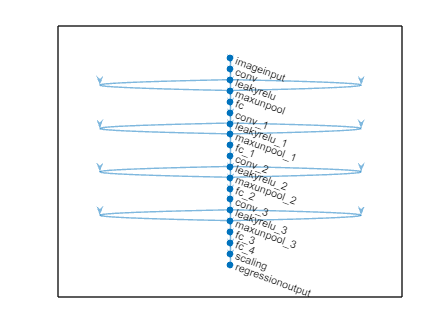

plot(lgraph);